# Problema 1 -Suplimentar

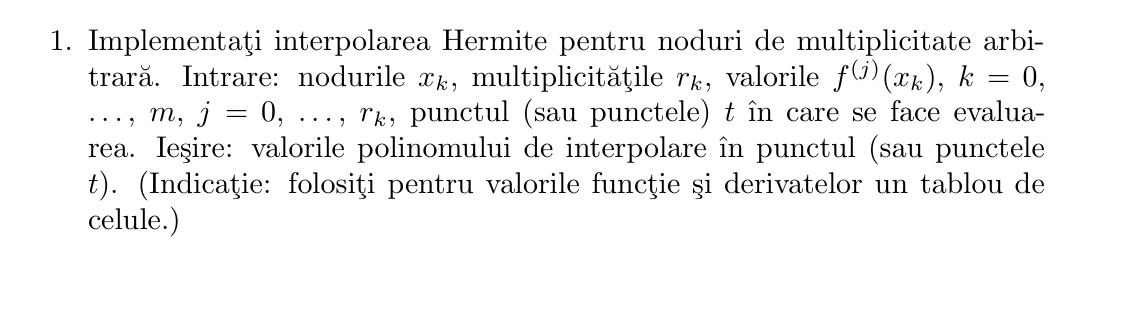

%PB1
function [p_val, coef, z] = interpolareHermite(x, f, df, x_eval)
% INTERPOLAREHERMITE - Interpolare Hermite cu noduri duble (forma Newton)
%
% INPUT:
%   x       - vector cu nodurile xi (lungime n)
%   f       - valorile functiei f(xi)
%   df      - valorile derivatei f'(xi)
%   x_eval  - punctele in care se evalueaza polinomul
%
% OUTPUT:
%   p_val   - valorile interpolate in punctele x_eval
%   coef    - coeficientii Newton ai polinomului Hermite
%   z       - vectorul de noduri extinse (cu dubluri)

    n = length(x);        % numarul de noduri initiale
    m = 2 * n;            % numarul de linii in tabela (fiecare nod apare de 2 ori)
    
    z = zeros(1, m);      % vectorul de noduri extinse: z_0, z_1, ..., z_{2n-1}
    Q = zeros(m, m);      % tabela Hermite de diferente divizate

    % P1, P2 
    for i = 1:m/2
        idx1 = 2*i - 1; % prima apariție
        idx2 = 2*i;     % a doua apariție (unde e derivata)
    
        z(idx1) = x(i);
        z(idx2) = x(i);
    
        Q(idx1, 1) = f(i);
        Q(idx2, 1) = f(i);
    
        if length(df) >= idx2
            Q(idx2, 2) = df(idx2); % doar aici e f'(x)
        end
        if i ~= 1
            Q(idx1, 2) = (Q(idx1, 1) - Q(idx1 - 1, 1)) / (z(idx1) - z(idx1 - 1));
        end
    end


    % P4 - Completam tabela Hermite (diferente divizate de ordin superior) 
    for i = 3:m
        for j = 3:i
            Q(i,j) = (Q(i,j-1) - Q(i-1,j-1)) / (z(i) - z(i-j+1));
        end
    end

    % P5 - Extragem coeficientii de pe diagonala
    coef = diag(Q);  % coeficientii din forma Newton

    % Evaluare polinom Hermite in punctele x_eval 
    p_val = zeros(size(x_eval));  % vector rezultat

    for k = 1:length(x_eval)
        val = coef(1);             % pornim cu primul coeficient
        produs = 1;

        for j = 2:m
            produs = produs * (x_eval(k) - z(j-1));
            val = val + coef(j) * produs;
        end

        p_val(k) = val;
    end
end

function este_derivabila = verificaDerivabilitateGlobala(f, x_noduri, tol)
% VERIFICADERIVABILITATEGLOBALA - Verifica daca functia f este derivabila
% in toate punctele din vectorul de noduri x_noduri.
%
% Aceasta functie compara derivata stanga si derivata dreapta numerica
% in fiecare punct dat. Daca toate diferentele sunt mai mici decat
% toleranta tol, functia se considera derivabila peste toate nodurile.
%
% INPUT:
%   f            - functie anonima (de tipul f = @(x) ...)
%   x_noduri     - vector cu punctele unde verificam derivabilitatea
%   tol          - toleranta (ex: 1e-4) sub care consideram ca derivata exista
%
% OUTPUT:
%   este_derivabila - true daca f este derivabila in toate punctele din x_noduri

    h = 1e-5;                     % pas mic pentru aproximare numerica
    este_derivabila = true;       % presupunem ca functia e derivabila

    % Parcurgem fiecare punct
    for i = 1:length(x_noduri)
        x0 = x_noduri(i);        % punctul curent

        % Derivata stanga si dreapta (finite differences)
        d_st = (f(x0) - f(x0 - h)) / h;
        d_dr = (f(x0 + h) - f(x0)) / h;

        % Verificam daca diferentele sunt prea mari
        if abs(d_st - d_dr) >= tol
            fprintf('[!] Functia NU este derivabila in x = %.5f\n', x0);
            este_derivabila = false;
            return;             % iesim imediat daca gasim o neregularitate
        end
    end
end

function df_val = calculeazaDerivataSigura(f, x_noduri)
% CALCULEAZADERIVATASIGURA - Calculeaza derivata functiei f in nodurile date
% folosind formula diferentei centrate, fara verificare prealabila.
%
% Aceasta functie presupune ca functia este deja derivabila.
% Derivarea se face cu o aproximare centrata de ordin 2.
%
% INPUT:
%   f         - functie anonima (ex: @(x) sin(x))
%   x_noduri  - vector cu punctele in care se calculeaza derivata
%
% OUTPUT:
%   df_val    - vector cu valorile aproximative ale derivatelor in punctele respective

    h = 1e-5;  % pas mic pentru derivare centrata

    % Aplicam formula derivatei centrate: f'(x) ≈ [f(x+h) - f(x-h)] / (2h)
    df_val = (f(x_noduri + h) - f(x_noduri - h)) ./ (2*h);
end

function [p_val, coef, z] = interpolareHermiteMultiplicitate(x, r, valori_derivate, x_eval)
% INTERPOLAREHERMITEMULTIPLICITATE - Pregateste datele si apeleaza interpolareHermite
%
% INPUT:
%   x               - noduri [x0, x1, ..., xm]
%   r               - vector de multiplicitati [r0, r1, ..., rm]
%   valori_derivate - celula: fiecare element contine [f(xk), f'(xk), ..., f^{rk}(xk)]
%   x_eval          - punctele unde vrem sa evaluam interpolarea
%
% OUTPUT:
%   p_val   - valorile interpolate
%   coef    - coeficientii Newton
%   z       - nodurile extinse

    % Construim nodurile extinse si derivatele
    x_extins = [];
    f_val = [];
    df_val = [];

    for i = 1:length(x)
        multiplicitate = r(i);
        derivate = valori_derivate{i};

        if length(derivate) < 2 && multiplicitate > 0
            error('Trebuie sa specifici cel putin f(x) si f''(x) daca multiplicitatea este > 0.');
        end

        % Adaugam de (ri+1) ori nodul
        for j = 0:multiplicitate
            x_extins(end+1) = x(i);    % acelasi nod
            f_val(end+1) = derivate(1);    % f(x)
            if j == 1
                df_val(end+1) = derivate(2);  % f'(x)
            elseif j > 1
                % folosim 0 pentru ca interpolareHermite nu va folosi df la j>1
                df_val(end+1) = 0;
            end
        end
    end

    % Apelam functia deja existenta
    [p_val, coef, z] = interpolareHermite(x_extins, f_val, df_val, x_eval);
end

% Functia de interpolat
f = @(x) x.^3 - 2*x.^2 + x + 1;

% Nodurile unde vrei sa construiesti interpolarea
x = [1, 2];
max_deriv = 2;        % cat de multe derivate vrei (f, f', f'' => 2)

% Verifica daca functia e derivabila in toate punctele
if ~verificaDerivabilitateGlobala(f, x, 1e-4)
    error('Functia nu este derivabila in toate nodurile. Hermite imposibil.');
end

% Construim vectorul de multiplicitati: fiecare nod va avea derivari pana la max_deriv
r = max_deriv * ones(size(x));

% Construim celula cu f(x), f'(x), f''(x)
val = cell(1, length(x));
h = 1e-5;

for i = 1:length(x)
    x0 = x(i);
    val_i = zeros(1, max_deriv + 1);

    val_i(1) = f(x0);  % f(x)

    if max_deriv >= 1
        val_i(2) = (f(x0 + h) - f(x0 - h)) / (2*h);  % f'
    end
    if max_deriv >= 2
        val_i(3) = (f(x0 + h) - 2*f(x0) + f(x0 - h)) / (h^2);  % f''
    end

    val{i} = val_i;
end

% Puncte de evaluare
x_eval = [1.5, 2];

% Apel interpolare Hermite cu multiplicitati
[p_val, coef, z] = interpolareHermiteMultiplicitate(x, r, val, x_eval);

% Afisare rezultate
fprintf('Valori interpolate in punctele:\n');

Valori interpolate in punctele:


disp(x_eval);

    1.5000    2.0000

